# Válogatott modellek a matematikai biológiában

# 1. gyakorlat

## Perron-Frobenius mátrixok hatványozása

#### Diffúzió a Perron-Frobenius diffúziós rendszer mátrix alakban.

Tekintsük $u: [0,\infty]\times[0,L] \to \mathbb{R}$függvényt, mely kielégíti a $u'_t(t,x) = u''_{xx}(t,x)$ diffúziós egyenletet és a Carl Neumann féle $u'_t(t,0) = u'_t(t,L) = 0$ peremfeltételt. Praktikus okokból csak véges időhorizonton vizsgáljuk a függvény viselkedését, vagyis $u: [0,T]\times[0,L] \to \mathbb{R}$.

Legyen $u_{i,j} = u(i\tau,jh)$, $i = 0,\dots,N_T, j = 0,\dots,N_L$, úgy, hogy $N_T \cdot \tau = T$és $N_L \cdot h = L$.

**Figyelem!** $\mu = \frac{\tau}{h^2}$-t úgy kell megválasztanunk, hogy $0 < \mu \le \frac{1}{2}$.

(Vajon mi történne, ha $\mu$-re ez nem teljesülne?)

mu = 0.1;

Az $A_N = \pmatrix{ 1 - \mu & \mu & 0 & \dots & 0 \cr \mu & 1 - 2\mu & \mu & \dots & 0 \cr \dots \cr 0 & 0 & 0 & \dots & 1 - \mu }$ mátrixot a `toeplitz` függvénnyel könnyedén létre lehet hozni. A `toeplitz` függvény diagonális ismétli a megadott első sort és oszlopot, lásd, `help toeplitz`. Az $N$alsó index az $A_N$-ben a Carl Neumann féle peremfeltételre utal. Ez a peremfeltétel megörzi a kezdeti anyag/energia mennyiségét.

$A_N$ mátrix méretét jelölje $n_A  = N_L+1$.

nA = 20;

A diffúziós $A_N$ mátrix elõállítása:

AN_elso_sora = [1-2*mu mu zeros(1,nA-2)];
AN = toeplitz(AN_elso_sora,AN_elso_sora);

A Neumann peremfeltételekre külön figyelni kell a mátrix sarkaiban.

AN(1,1) = 1-mu;
AN(end,end) = 1-mu;

Számítsik ki az $A_N$ mátrix sajátértékeit (`D`) és sajátvektorait (`S`).

[S,D] = eig(AN);
Eigenvalues = diag(D)'

Eigenvalues =     0.6025    0.6098    0.6218    0.6382    0.6586    0.6824    0.7092    0.7382    0.7687    0.8000    0.8313    0.8618    0.8908    0.9176    0.9414    0.9618    0.9782    0.9902    0.9975    1.0000


Kezdeti feltétel (pl.kiindulási koncentráció eloszlás, vagy rúd hőmérsékletének kezdeti eloszlása, egy autópálya mentén a járművel kezdeti sűrűsége, stb.), jelölje $x_0$.

x0 = zeros(nA,1);
x0(8:13) = 1;

Az időhorizont amelyen a dinamikát vizsgálom jelölje $N_T = T/\tau \in \mathbb N$

N_T = 800;

Számoljuk ki $x_T$-t anélkül, hogy az köztes időben kapott $x_1, x_2, \dots, x_{T-1}$értékeket kiszámolnám, tudva, hogy $x_n = (A_N^n) \, x_0$.

AN_T = AN^N_T;
[S_T,D_T] = eig(AN_T);
xT = AN_T*x0;

Számoljuk ki lépésenként is egyenként $x_1, x_2, \dots, x_{T-1}, x_T$-t, közben azt is vizsgáljuk, hogy a mátrixhatványok sorában miképp alakulnak a sajátértékek.

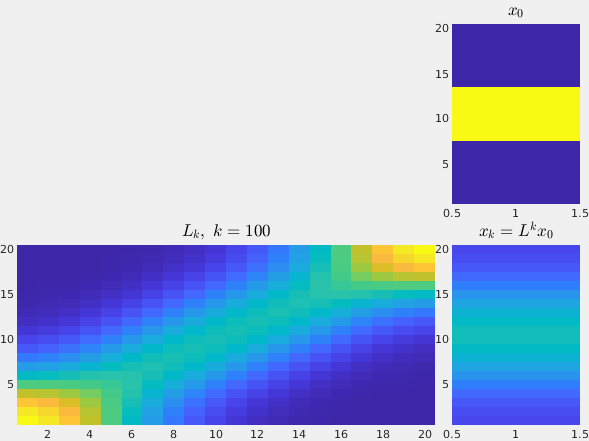

x = x0; 
eigs = zeros(nA,N_T);
fig = figure(123);
fig.Visible = 'on';

Tl = tiledlayout(2,4,"TileSpacing","tight","Padding","tight","TileIndexing","rowmajor");

ax1 = nexttile(4); hold on, grid on, box on
Im0 = imagesc(x0);
clim([0,1])
axis tight
title('$x_0$','Interpreter','latex','FontSize',12)

ax2 = nexttile(5,[1,3]); hold on, grid on, box on;
ImA = imagesc(AN);
axis tight
Tl = title("$L_k,~ \makebox[2cm]{$k = 1\hfill$}$",'Interpreter','latex','FontSize',12);

ax3 = nexttile(8); hold on, grid on, box on;
Imk = imagesc(x0);
clim([0,1])
axis tight
title('$x_k = L^k x_0$','Interpreter','latex','FontSize',12)

Ak = eye(nA);
xk = x0;
for k = 1:T
    Ak = Ak*AN;
    xk = AN*xk;
    se_hatv = eig(Ak);
    
    ImA.CData = Ak;
    Imk.CData = xk;

    Tl.String = "$L_k,~ k = " + num2str(k) + "$";
    drawnow
end



for k = 1:N_T 
    AN_T = AN^k;

    eigs(:,k) = eig(AN_T); % sajátértékeket mindig eltárolom
    x = AN*x;
    
    %a diffúziós folyamat ábrázolása 
    subplot(6,4,[13:15,17:19,21:23]);
    imagesc(AN_T) %ábrázolom a mátrixot
    clim([0,1]); %a színskála határainak fixálása (egyébként automatikusan módosul a skála a legnagyobb és legkisebb érték közé)
    title(['hatvány: ', num2str(k)])
    subplot(6,4,[4,8,12]);
    imagesc(x0)
    clim([0,1]);
    title('kezdeti koncentráció értékek')
    subplot(6,4,[16,20,24]);
    imagesc(x)
    clim([0,1]);
    title(['koncentráció értékek ', num2str(k), ' lépés diffúzió után'])
    drawnow
end
return

figure;
plot(1:N_T, real(eigs), '.b'); %ábrázolom a sajátértékeket, ezek jellemzik a mátrixot (az abszolútértékben maximális leginkább) 
xlim([1, N_T]);
xlabel('hatványok');
ylabel('sajátértékek');
title('A mátrix sajátértékeinek alakulása a hatványozással.');

A legnagyobb sajátértékhez csupa 1-es sajátvektor tartozik, ez lesz domináns.

A hatványozással, avagy az idõ múlásával, ezért van kiegyenlítõdés a folyamat elõre haladtával

a kis sé-hez tartozó sv gyakran vált elõjelet, oszcillál, de ez hamar

eltûnik, lecseng a hatványozásnál

a<0.5, akkor max sé 1 (anyagmegmaradásos esetben), minimális -1-nél nagyobb, a max dominál hatványozásnál a többi eltûnik hatványozással

(ha a=0.5, akkor +- -ban 1 erõs hullám szõrösödik ez 2 tag marad meg legtovább hatványozással, szimmetria 

a>0.5, akkor max sé 1 (anyagmegmaradásos esetben), minimális -1-nél kisebb, ez száll el hatványozással, oszcillálva, ez a domináns